**Trecho inicial de uma música simples, com um só instrumento(piano)**

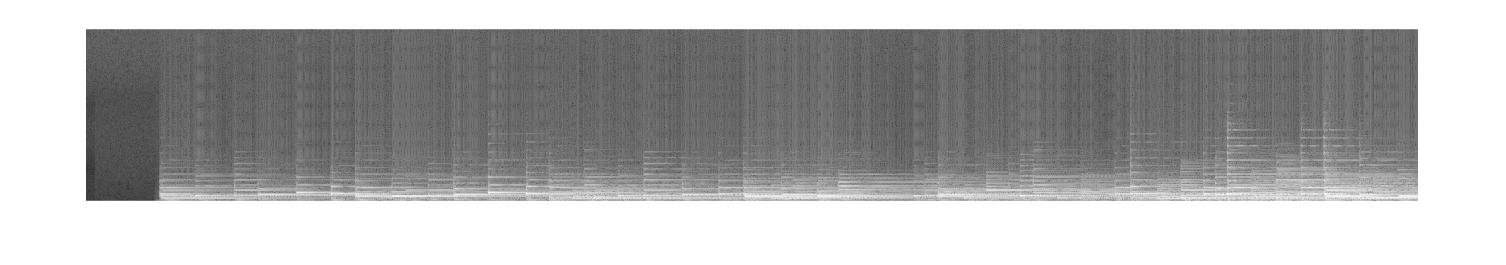

%Primeiro definimos a entrada do algoritmo
[amostras, freq_amostragem] = audioread("Piano.wav");
duracao = length(amostras) / freq_amostragem;
%Em seguida chamamos a função criada
[espectrograma, freq_pico] = espectrograma_stft(amostras,duracao,freq_amostragem);

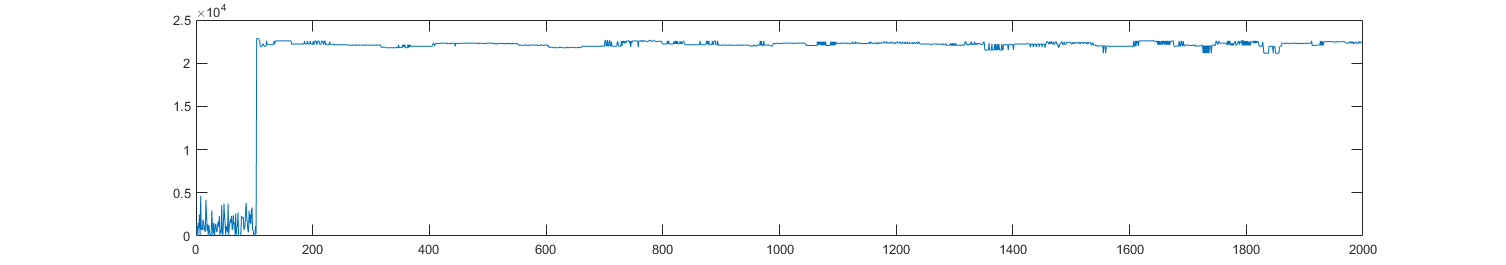

%Essa função já nos retorna o espectrograma do sinal de entrada
%Agora mostraremos o gráfico da frequencia de pico

plot(freq_pico);

%É possível notar que a frequencia de pico durante a música ficou em torno
%de 20KHz 


**Sinal de voz dizendo "Três pratos de trigo para três tigres tristes"**

%Primeiro definimos a entrada do algoritmo
[amostras, freq_amostragem] = audioread("TigreTriste.wav");
duracao = length(amostras) / freq_amostragem;
%Em seguida chamamos a função criada
[espectrograma, freq_pico] = espectrograma_stft(amostras,duracao,freq_amostragem);
%Essa função já nos retorna o espectrograma do sinal de entrada
%Agora mostraremos o gráfico da frequencia de pico

plot(freq_pico);
%Com o sinal de voz é possivel notar que a frequência de pico é mais
%instável, isso dá ao fato de que a nossa voz vai aumentando e diminuindo a
%frequencia de acordo com o que falamos durante uma frase.